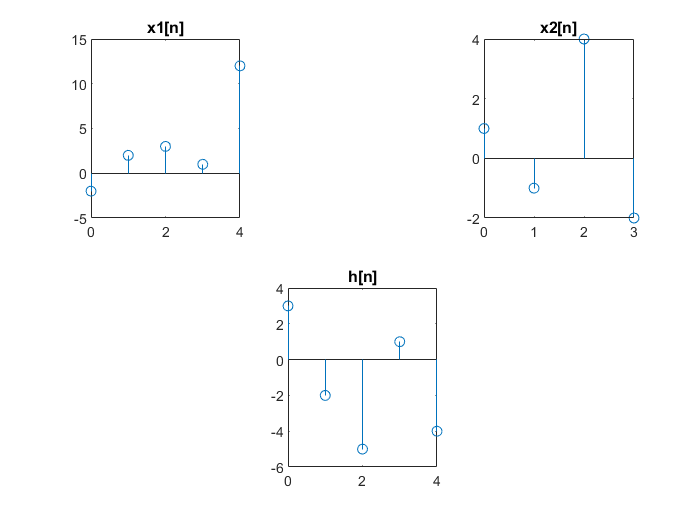

close all
clc
o=5;
p=0:o-1;
a=0:o-2;
x1=[-2 2 3 1 12];
subplot(2,3,1);stem(p,x1);title('x1[n]');
x2=[1 -1 4 -2];
subplot(2,3,3);stem(a,x2);title('x2[n]');
h=[3 -2 -5 1 -4];
subplot(2,3,5);stem(p,h);title('h[n]');

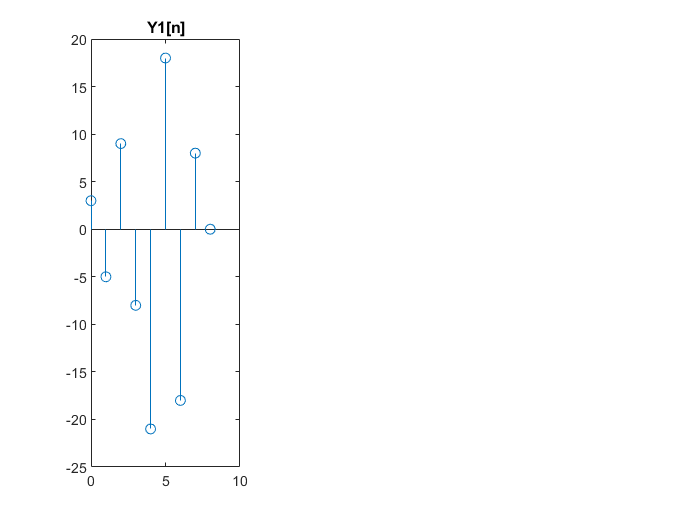

% convolution
m=length(x1);
o=length(x2);
n=length(h);
k=max(o,m);
X1=[x1,zeros(1,n)];
X2=[x2,zeros(1,n)];
H=[h,zeros(1,k)];
for i=1:n+k-1
    Y1(i)=0;
    for j=1:k
        if(i-j+1>0)
            Y1(i)=Y1(i)+X2(j)*H(i-j+1);
        end
    end
end
% plot results
figure;
p=0:8;
subplot(1,3,1);stem(p,Y1);title('Y1[n]');